# Number Pages in a PDF Template

This example shows how to number pages of a report using a PDF template. It defines a right-aligned page number for odd pages and a left-aligned page number for even pages by using two different footers. The following image shows two pages in a document created using the example template:

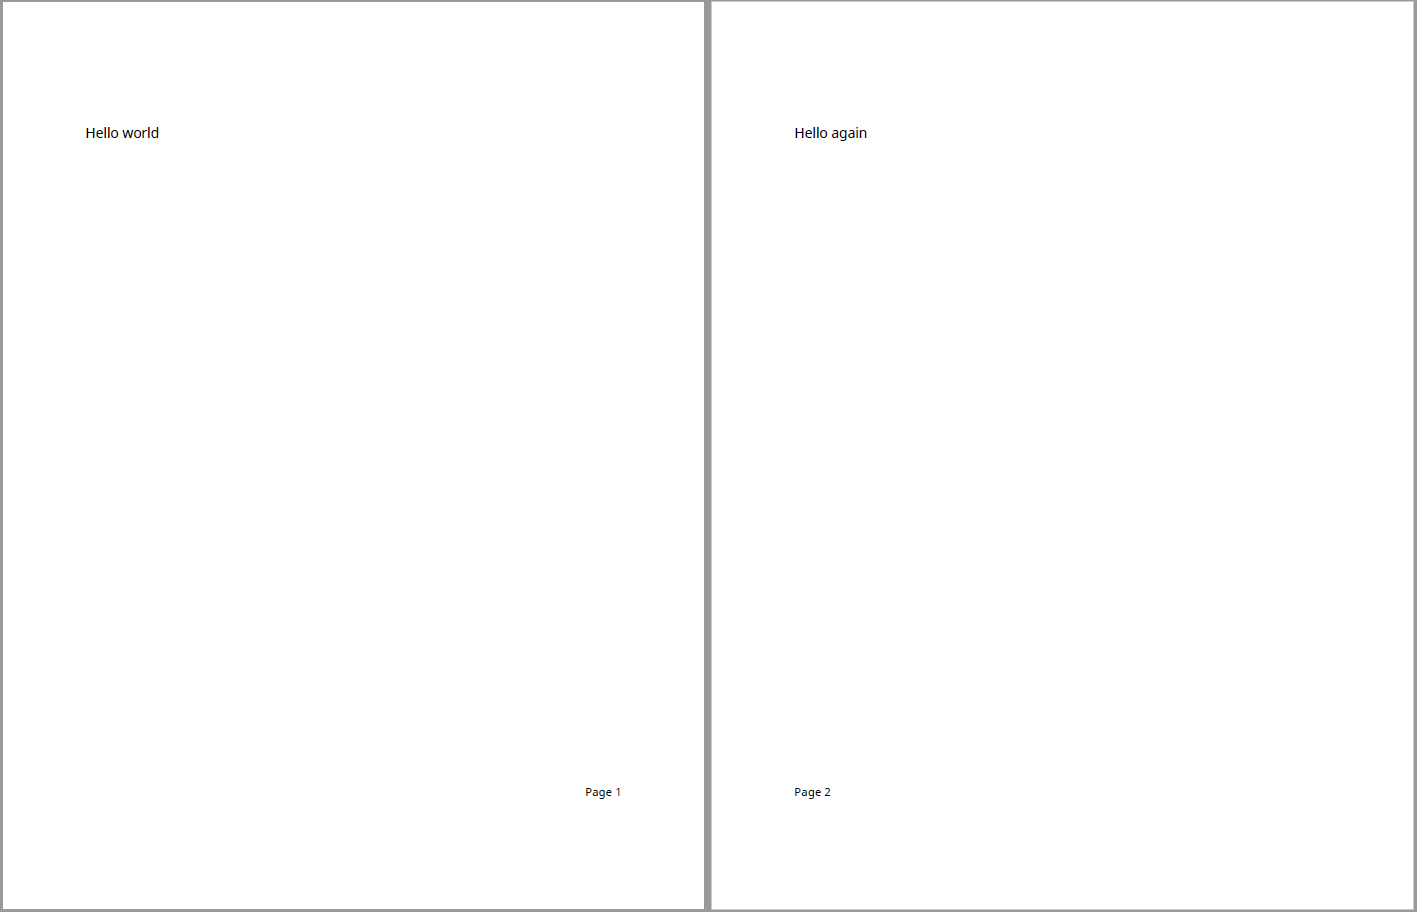

## Create a Template

Create a PDF template, `myPDFTemplate.pdftx`, in the current working directory. Unzip the template for editing. A reference template that already includes the footers for the example is available in `exampleTemplate.pdftx`. 

mlreportgen.dom.Document.createTemplate("myPDFTemplate","pdf");
unzipTemplate("myPDFTemplate.pdftx", "myPDFTemplate_pdftx");
%unzipTemplate("exampleTemplate.pdftxt", "exampleTemplate_pdftx");

## Define Footer Contents

In `myPDFTemplate_pdftx\docpart_templates.html`, define template parts that hold the content of the footers. In the `<dplibrary>` tags, create `<dptemplate>` elements named `MyPageFooter` for odd pages and `MyEvenFooter` for even pages. Create paragraphs that contain the text included in each footer as well as `page` elements where the page number should be placed. Set the `text-align` style to `right` for `MyPageFooter` and `left` for `MyEvenFooter`. For example:

## Create Footer Elements

In the body section of `myPDFTemplate_pdftx\root.html`, uncomment the `<layout>` element and add two `<pfooter>` elements. Set the `type` and `template-name` attributes as shown in the following example HTML code. The `default` type footer is used for first and odd pages. The `even` type footer is used for even pages. The `template-name` attributes are set to the names of the template parts defined earlier. To specify the number of the starting page, add a `<pnumber>` element.

## Zip the Template

Zip the template files back to the `myPDFTemplate.pdftx` template package.

zipTemplate('myPDFTemplate.pdftx', 'myPDFTemplate_pdftx');

## Use the Template

Use the template by specifying the template name when creating the document. The following code uses the reference template `exampleTemplate.pdftx` to create a document. To use the template modified by the example, replace `exampleTemplate` with `myPDFTemplate`.

import mlreportgen.dom.*

d = Document("myDocument", "pdf", "exampleTemplate");
open(d);

append(d, "Hello world");
append(d, PageBreak());
append(d, "Hello again");
append(d, PageBreak());
append(d, "Hello again");
append(d, PageBreak());
append(d, "Hello again");
append(d, PageBreak());
append(d, "Hello again");

close(d);
rptview(d);

*Copyright 2019 The MathWorks, Inc.*